modulePath = 'C:\Users\Asus\Studia\Indywidualny Program Studiów\IPS - Projekt\dane - semestr 5\MATLAB_project\python_modules';
insert(py.sys.path, int32(0), modulePath);
load('C:\Users\Asus\Studia\Indywidualny Program Studiów\IPS - Projekt\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat')

function results_py = model_hybrid(y_train, y_test, step_length,  ma_window, season_period)
    py_model = py.importlib.import_module("model_hybrid");
    results_py = py_model.model_hybrid(...
        y_train, ... 
        y_test, ...
        step_length, ...
        pyargs('ma_window', ma_window, 'season_period', season_period, 'verbose', true) ...
    ).double';
end

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);

train_data = ab_diff_train_norm;
test_data = ab_diff_test_norm;

dlugosc_testu_oryginalna = 2880; % Horyzont w oryginalnej dziedzinie czasu (2880 próbek)

test_length = dlugosc_testu_oryginalna;
step_length = 16;

% Przewidywania A1 - model hybrydowy
prediction = model_hybrid(train_data, test_data(1:test_length), step_length, 32, 96*7);

Step: 1 / 180
Step: 2 / 180
Step: 3 / 180
Step: 4 / 180
Step: 5 / 180
Step: 6 / 180
Step: 7 / 180
Step: 8 / 180
Step: 9 / 180
Step: 10 / 180
Step: 11 / 180
Step: 12 / 180
Step: 13 / 180
Step: 14 / 180
Step: 15 / 180
Step: 16 / 180
Step: 17 / 180
Step: 18 / 180
Step: 19 / 180
Step: 20 / 180
Step: 21 / 180
Step: 22 / 180
Step: 23 / 180
Step: 24 / 180
Step: 25 / 180
Step: 26 / 180
Step: 27 / 180
Step: 28 / 180
Step: 29 / 180
Step: 30 / 180
Step: 31 / 180
Step: 32 / 180
Step: 33 / 180
Step: 34 / 180
Step: 35 / 180
Step: 36 / 180
Step: 37 / 180
Step: 38 / 180
Step: 39 / 180
Step: 40 / 180
Step: 41 / 180
Step: 42 / 180
Step: 43 / 180
Step: 44 / 180
Step: 45 / 180
Step: 46 / 180
Step: 47 / 180
Step: 48 / 180
Step: 49 / 180
Step: 50 / 180
Step: 51 / 180
Step: 52 / 180
Step: 53 / 180
Step: 54 / 180
Step: 55 / 180
Step: 56 / 180
Step: 57 / 180
Step: 58 / 180
Step: 59 / 180
Step: 60 / 180
Step: 61 / 180
Step: 62 / 180
Step: 63 / 180
Step: 64 / 180
Step: 65 / 180
Step: 66 / 180
Step: 67 / 180
Step

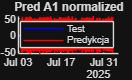

% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:test_length), test_data(1:test_length), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:test_length), prediction, 'Color','red','DisplayName','Predykcja');
title('Pred A1 normalized');
legend;

y_test = test_data(1:length(prediction))';

mae_score = mae(y_test, prediction)

mae_score = 35.8615

mape_score = mape(y_test, prediction)

mape_score = 111.3148

rmse_score = rmse(y_test, prediction)

rmse_score = 40.1543

r2_classic = R2_classic(y_test, prediction)

r2_classic = -1.3452e+04

r2_alt = R2_alt(y_test, prediction)

r2_alt = 1.3460e+04

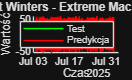


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(prediction)), ab_diff_test_norm(1:length(prediction)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(prediction)), prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja Holt Winters - Extreme Maching Learning: A1")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   prediction(1:dlugosc_testu_oryginalna)', ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'}');

writetable(T_z_czasem, "pred_ab_HYBRYDA_" + num2str(step_length) + "_month.xlsx");